# **Singing board**

#### Realtime Interaction Performance

#### SMC8 - Juan Alonso - jalons19@student.aau.dk

## Global vars

global sr T;
sr = 44100; %Sampling rate
T  = 1/sr;  %Sampling period

## Formant

vowel_a = [[600,1040,2250,2450,2750];
    [60,70,110,120,130]];

vowel_e = [[400,1620,2400,2800,3100];
    [40,80,100,120,120]];

vowel_i = [[250,1750,2600,3050,3340];
    [60,90,100,120,120]];

vowel_o = [[400, 750,2400,2600,2900];
    [40,80,100,120,120]];

vowel_u = [[350, 600,2400,2675,2950];
    [40,80,100,120,120]];

vowel_olivia_a = [[1211, 1862,3683,5843];
    [60,70,110,120]];
vowel_olivia_e = [[690, 2559,3470,5628];
    [40,80,100,120]];
vowel_olivia_i = [[390, 2933,3589,5301];
    [40,80,100,120]];
vowel_olivia_o = [[663, 1283,3836,5340];
    [40,80,100,120]];
vowel_olivia_u = [[323, 1007,3494,5437];
    [40,80,100,120]];

vowel = vowel_olivia_u;
filename = 'olivia_u';
num_formants = 4;

## Filters

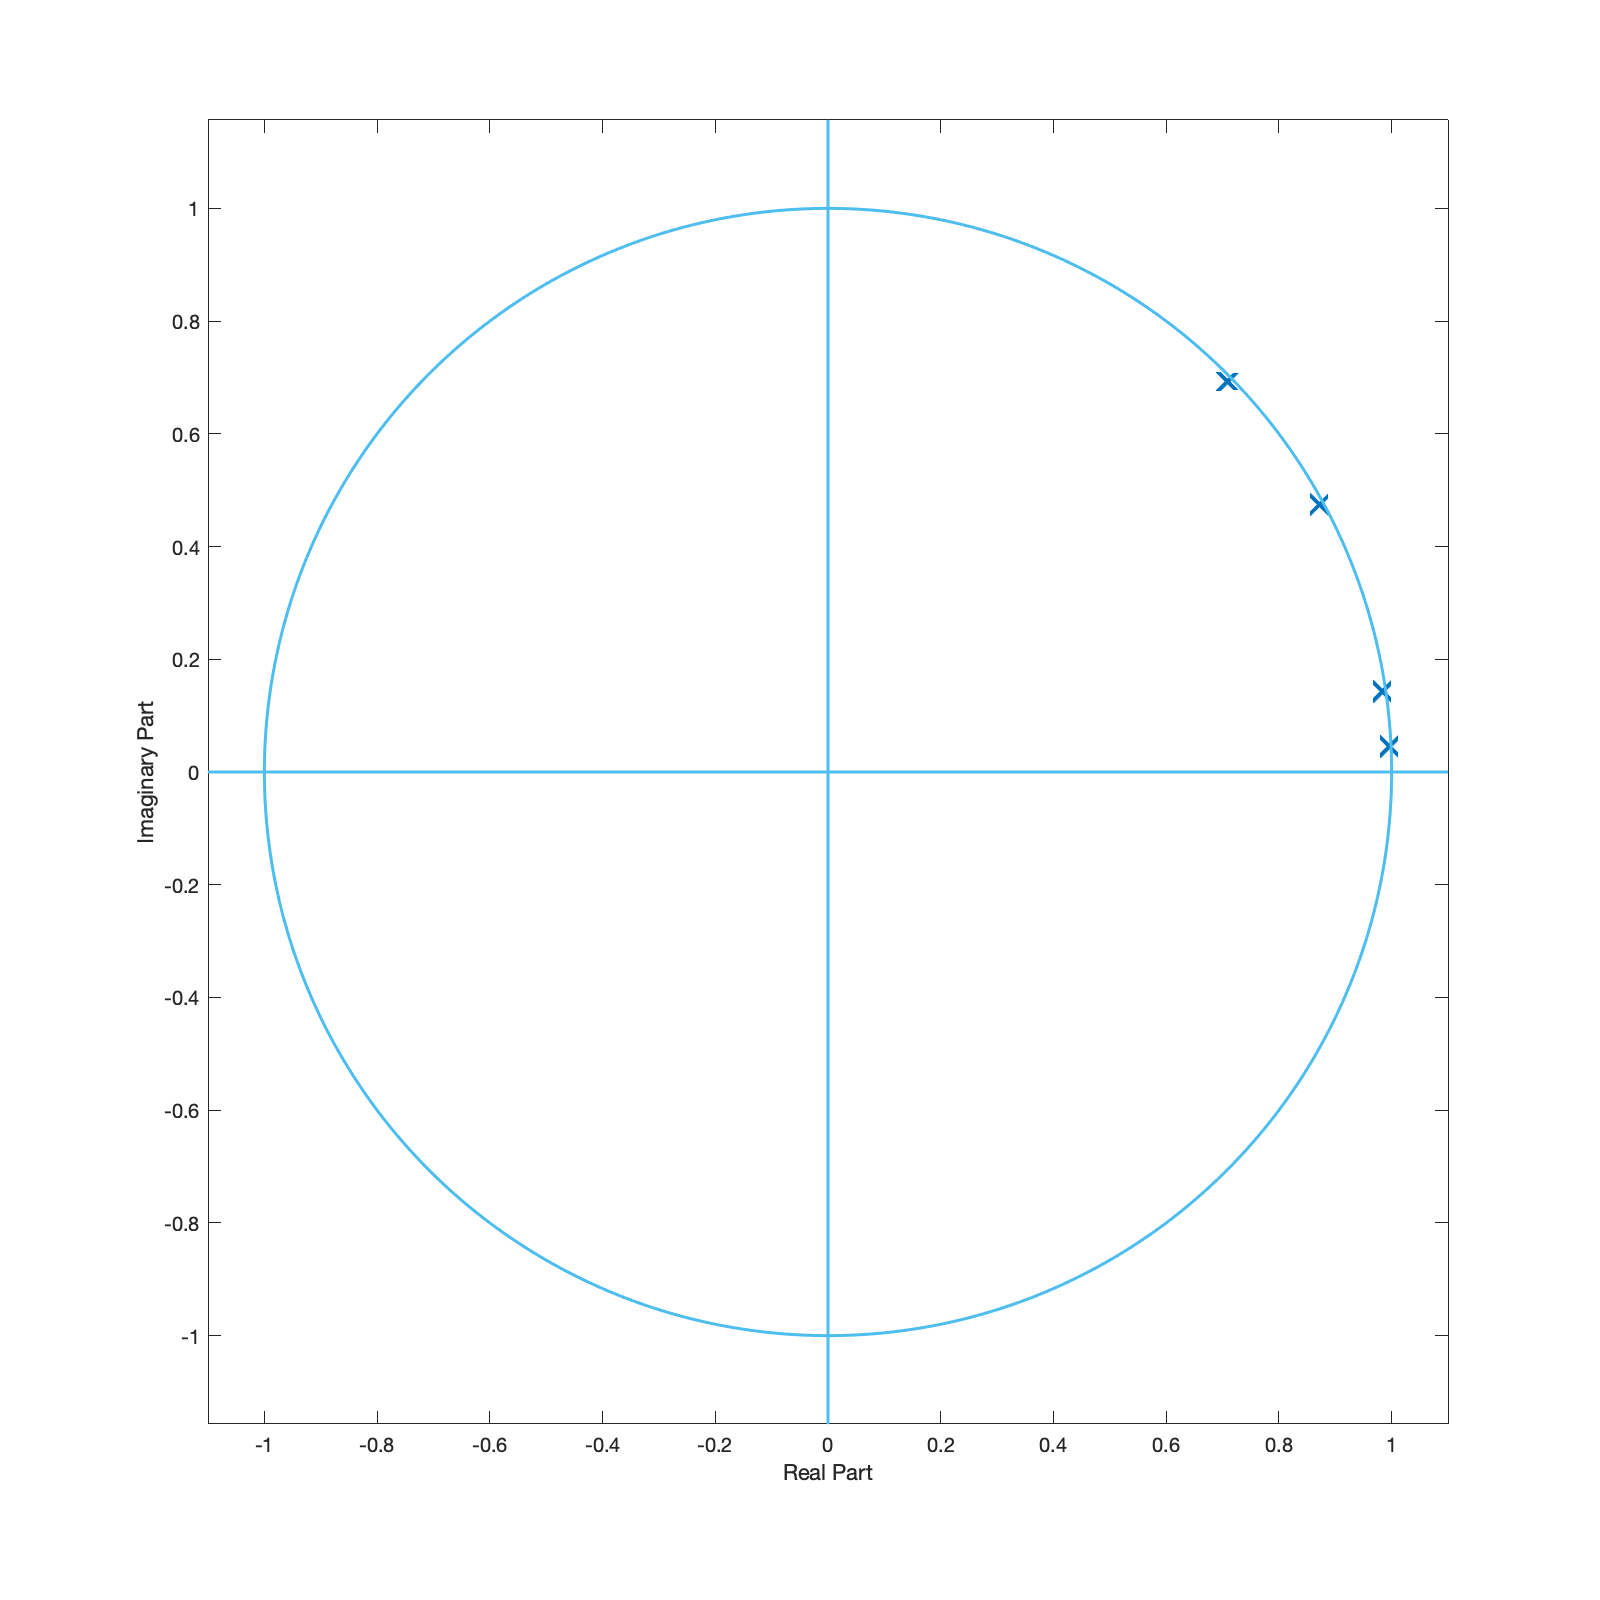

impulseTrain = impTrain(64);

F  = vowel(1,1:num_formants); %formant frequencies (Hz)
BW = vowel(2,1:num_formants); %formant bandwidths (Hz)

R = exp(-pi * BW * T);      % Pole radii for 3dB bandwidth (https://www.dsprelated.com/freebooks/filters/Bandwidth_One_Pole.html#sec:polebw)
theta = 2 * pi * F * T;     % Pole angles
poles = R .* exp(1i*theta); % Complex poles

fig = figure;
set(fig, 'Position', [0 0 800 800])
figure(fig);
[hz,hp,ht] = zplane([],(poly(poles)));
set(findobj(hp, 'Type', 'line'), 'LineWidth', 2, 'MarkerSize',12, 'Color', '#0072BD');
set(findobj(ht, 'Type', 'line'), 'LineWidth', 1.5, 'LineStyle', '-', 'Color', '#4DBEEE');

%saveas(gcf,sprintf('sin_filters_%s.png', filename))
y_filter =zeros(1,numel(impulseTrain));
for i = 1:num_formants
    A = [1, -2*R(i)*cos(theta(i)), R(i)^2]
    y_filter = y_filter + filter(1,A,impulseTrain);
    %freqz(B,A);
end

A =     1.0000   -1.9922    0.9943


A =     1.0000   -1.9682    0.9887


A =     1.0000   -1.7448    0.9859


A =     1.0000   -1.4172    0.9830


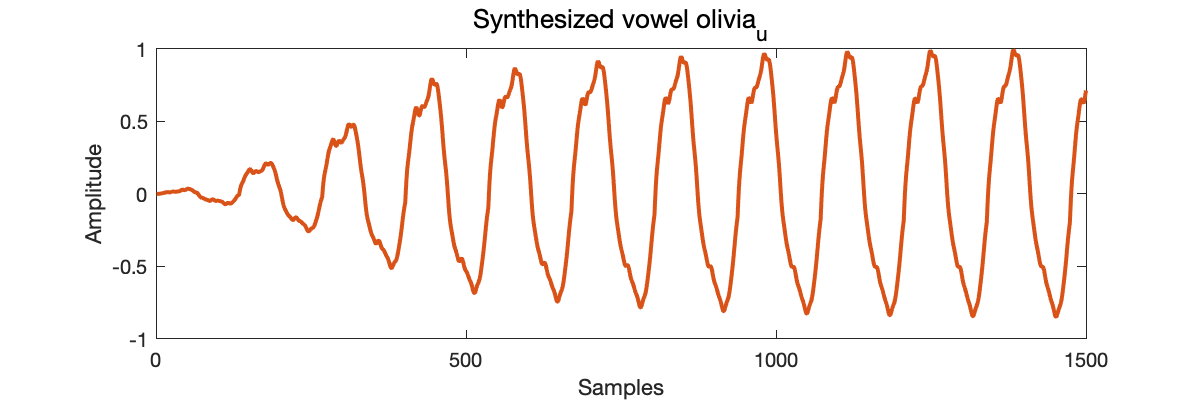

envelope = 0:1/440:1;
y_filter(1:441) = y_filter(1:441) .* envelope;
y_filter(end-440:end) = y_filter(end-440:end) .* (1-envelope);


y_filter = y_filter/max(abs(y_filter));
audiowrite(sprintf('sin_filters_%s.wav',filename),y_filter,sr);
soundsc(y_filter, sr)
fig = figure;
set(fig, 'Position', [0 0 600 200])
figure(fig);

plot((1:1500), y_filter(1:1500),'LineWidth',2, 'DisplayName',sprintf('Vowel %s',filename), 'color','#D95319')

title(sprintf('Synthesized vowel %s', filename), 'FontSize',13, 'FontSmoothing','on', 'FontWeight','normal');
xlabel('Samples')
ylabel('Amplitude')
axis([0 1500 -1 1])

%saveas(gcf,sprintf('sin_filters_vowel_%s.png', filename))

# **Impulse train **

Helper function to calculate the impulse train 

function impulseTrain = impTrain(midinote)

global sr

%frequency (Hz) of the impulses
f0 = floor(440*2^((midinote-69)/12));

%duration of the impulse train in seconds
duration = 3;

%Period in samples
impulsePeriod = floor(sr/f0);

time = 1:sr*duration;

%One-liner to create the impulse train.
impulseTrain  = double(mod(time-1, impulsePeriod) == 0);

end